
opts = birdOpts();
%dataTable = readtable("/Users/nickyvaldecanas/Desktop/cs470/Soundscapes/warbleR_comb.csv", opts);
fullData = readtable("/Users/nickyvaldecanas/Desktop/cs470/Soundscapes/CSVs/300Each.csv", opts);
%warblerData = readtable("/Users/nickyvaldecanas/Desktop/cs470/Soundscapes/CSVs/warblerTest120.csv", opts);

[birdObjects] = getBirdData(fullData, "None");

[svmModel] = svmTrain(birdObjects,"Features");

[svm1D] = svmTest(svmModel,testBirds,"Features");

testBCs = [testBirds.BirdCode];
accuracy = mean(svm1D == testBCs)

accuracy =    0.647345132743363


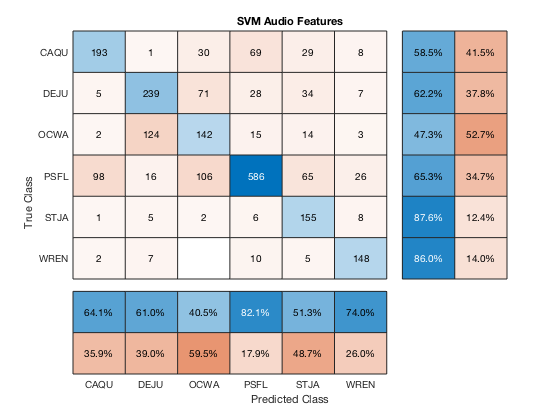

cm = confusionchart(testBCs,svm1D);
cm.Title = 'SVM Audio Features';
conMat = cm.NormalizedValues;
cm.RowSummary = 'row-normalized'; cm.ColumnSummary = 'column-normalized';

cmDiag = diag(conMat);
numLabels = size(cmDiag,1);
f1Scores = zeros([1 numLabels]);
for i=1:numLabels
    TP = cmDiag(i);
    falseRow = sum(conMat(i,:),2);
    falseCol = sum(conMat(:,i),1);
    FP = abs(TP - falseRow);
    FN = abs(TP - falseCol);
    TN = TP - FP - FN;
    precision = double(TP ./ (TP+FP));
    recall = double(TP ./ (TP+FN));
    score = 2 * (precision*recall) ./ (precision+recall);
    f1Scores(i) = score;
end
avgf1Score = mean(f1Scores);
f1Scores

f1Scores =    0.611727416798732   0.615979381443299   0.436251920122888   0.727498448168839   0.647181628392484   0.795698924731183


avgf1Score

avgf1Score =    0.639056286609571


load birds3K.mat

tic;
pca1DWarblerResults = runTests(birdObjects,pcaModel1D, warblerPad, "PCA","Features");
elapsed = toc/60;
fprintf('TIC TOC: %g\n', elapsed);


testBCs = [warblerPad.BirdCode];

Unable to resolve the name warblerPad.BirdCode.

accuracy = mean(pca1DWarblerResults == testBCs)
cm = confusionchart(testBCs,pca1DWarblerResults);
cm.Title = 'SVM 2D Spectograms';
conMat = cm.NormalizedValues;
cm.RowSummary = 'row-normalized'; cm.ColumnSummary = 'column-normalized';
cmDiag = diag(conMat);
numLabels = size(cmDiag,1);
f1Scores = zeros([1 numLabels]);
for i=1:numLabels
    TP = cmDiag(i);
    falseRow = sum(conMat(i,:),2);
    falseCol = sum(conMat(:,i),1);
    FP = abs(TP - falseRow);
    FN = abs(TP - falseCol);
    TN = TP - FP - FN;
    precision = double(TP ./ (TP+FP));
    recall = double(TP ./ (TP+FN));
    score = 2 * (precision*recall) ./ (precision+recall);
    f1Scores(i) = score;
end
avgf1Score = mean(f1Scores);
f1Scores
avgf1Score


%SVM Model
% ResultSVM1D = svmFunction(trainBirds,trainMatrix,testBirds,testMatrix);
% ResultSVM2D = svmFunction(trainBirds,trainSpecMat,testBirds,testSpecMat);


% N = size(trainMatrix,2);
% svmModel = {};
% svmTrainData = trainMatrix';
% trainBCIDs = [];
% for i = 1:N
%     %svmTrainData(i,:) = cat(2,mean(trainBirds(i).Features),std(trainBirds(i).Features));
%     trainBCIDs(i) = trainBirds(i).BirdCodeID;
% end
% rng(1);
% Y = trainBCIDs;
% classes = unique(Y);
% for j = 1:numel(classes)
%     index = (Y == classes(j));
%     svmModel{j} = fitcsvm(svmTrainData,index,"ClassNames",[false true],...
%         "Standardize",true);%,"KernelFunction","rbf","BoxConstraint",1)
% end

% %Create 
% testSize = size(testMatrix,2);
% svmTestData = testMatrix';
% testBCIDs = [];
% orginalBCIDs =[];
% for t = 1:testSize
%     %svmTestData(t,:) = cat(2,mean(pcaModel(t).Features),std(pcaModel(t).Features));
%     originalBCIDs(t) = testBirds(t).BirdCodeID;
%     %testBCIDs(t) = pcaResult(t).BirdCodeID;
% end
% originalBCIDs
% %testBCIDs

% %Predict
% testScores = [];
% correct = 0;
% for test = 1:testSize
%     svmTestVec = svmTestData(test,:);
%     for j = 1:numel(classes)
%         [~,score] = predict(svmModel{j},svmTestVec);
%         Scores(:,j) = score(:,2);
%     end
%     [~,svmPredBC] = max(Scores,[],2);
%     pcaBC = originalBCIDs(test);
%     if(pcaBC == svmPredBC)
%         correct = correct +1;
%     end
%     testScores(test) = svmPredBC;
% end
% %compareResults = cat(1,testBCIDs,testScores);
% testScores
% accuracy = correct/testSize


% fintime = cputime;
% elapsed = toc;
% time2   = clock;
% fprintf('TIC TOC: %g\n', elapsed);
% fprintf('CPUTIME: %g\n', fintime - initime);
% fprintf('CLOCK:   %g\n', etime(time2, time1));

Some statatistics on the data set



birdcodes = unique(fullData(:,"birdcode"));
for i=1:size(birdcodes,1)
    bird = birdcodes(i,"birdcode").Variables;
    roiCount = 0;
    dur = 0;
    durations = [];
    frequencies = [];
    freqCount = 1;
    for row=1:size(fullData,1)
        birdTable = fullData(row,"birdcode").Variables;
        if(birdTable ==  bird)
            roiCount = roiCount + 1;
            dur = single(fullData(row, "x2").Variables) - single(fullData(row, "x1").Variables);
            % single() makes it more accurate to the number in the csv file
            frequencies(freqCount) = single(fullData(row, "y2").Variables);
            frequencies(freqCount +1) =single(fullData(row, "y1").Variables);
            durations(roiCount) = dur;
            freqCount = freqCount +2;
        end
    end
    maxDur = max(durations(1,:));
    aveDur = mean(durations(1,:));
    maxFreq = max(frequencies(1,:));
    aveFreq = mean(frequencies(1,:));
    fprintf(' ROIs for %s: %d \n', bird,roiCount);
    fprintf(' Average Duration: %f \n',aveDur);
    fprintf(' Longest Duration: %f \n',maxDur);
    fprintf(' Average Frequency: %f \n',aveFreq);
    fprintf(' Highest Frequency: %f \n',maxFreq);
    fprintf(' ***************************** ');
end

